# Analysis of Monte Carlo Results

Analysis the simulation results in more detail. In particular, consider any variation caused by the signal-to-noise ratio. 

## Load Monte Carlo simulation results

Load the data from the Monte Carlo simulation. 

% Find base directory
basedir = fileparts(pwd);

% Set data directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% Set model director and file
modeldir = fullfile(basedir,"data","Models");
modelfilename = "ModelBaggedTreesDWPT5Lvl.mat";
% model variable name is mdlBag5lvl
waveletName = 'coif2';
waveletLevels = 5; 

% Set Monte Carlo directory and file
mcfolder = fullfile(basedir,"data","MonteCarlo");
mcfilename = "mcBagged5LvlResults.mat";

% Create pool of MATLAB workers
% tic; parpool('local',4); toc

% Load data
load(fullfile(mcfolder,mcfilename))

## Overall statistics

% Overall statistics
summary(tmcoutput)


Variables:

    BlockLength: 100×1 double

        Values:

            Min         1.024e+05  
            Median      1.024e+05  
            Max         1.024e+05  

    SignalFile: 100×1 string

    SignalStartIndx: 100×1 double

        Values:

            Min                3783    
            Median       7.7116e+05    
            Max          7.2946e+06    

    ContaminatedTrue: 100×1 logical

        Values:

            True             47        
            False            53        

    FracBlockContaminated: 100×1 double

        Values:

            Min                     0        
            Median                  0        
            Max               0.99979        

    ContaminationStartIndx: 100×1 double

        Values:

            Min                    0          
            Median                 0          
            Max                60697    

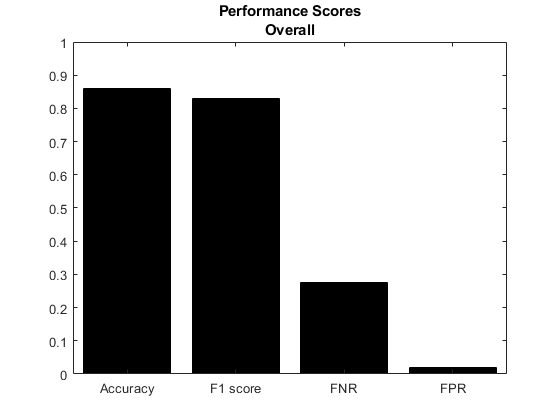

% Overall scores
[acc,fpr,fnr,f1] = scoreModel(tmcoutput.ContaminatedTrue,tmcoutput.ContaminatedPred);
scoresOA.acc = acc;
scoresOA.f1 = f1;
scoresOA.fpr = fpr;
scoresOA.fnr = fnr;
% Plot scores for comparison
c = categorical({'Accuracy','F1 score','FNR','FPR'});
bar(c,[acc; f1; fnr; fpr],'FaceColor','k');
ylim([0 1])
title({'Performance Scores';'Overall'})

## Contaminated files only

% Contaminated files only
tcontaminated = tmcoutput(tmcoutput.ContaminatedTrue == 1,:);
summary(tcontaminated)


Variables:

    BlockLength: 47×1 double

        Values:

            Min         1.024e+05  
            Median      1.024e+05  
            Max         1.024e+05  

    SignalFile: 47×1 string

    SignalStartIndx: 47×1 double

        Values:

            Min               24808    
            Median       7.9589e+05    
            Max          7.2946e+06    

    ContaminatedTrue: 47×1 logical

        Values:

            True             47        
            False             0        

    FracBlockContaminated: 47×1 double

        Values:

            Min               0.26244        
            Median            0.66003        
            Max               0.99979        

    ContaminationStartIndx: 47×1 double

        Values:

            Min                   22          
            Median             12418          
            Max                60697          

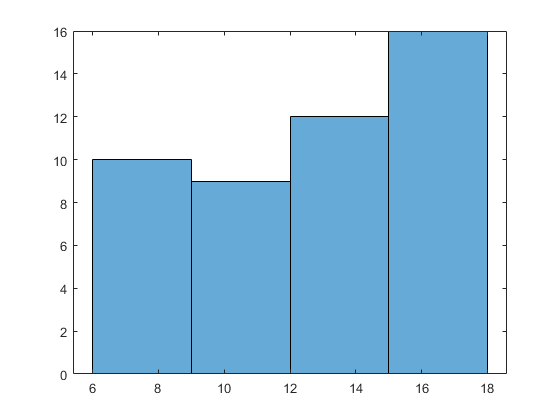

% Signal-to-noise ratio
edges = 6:3:18;
histogram(tcontaminated.SNRdB,edges)

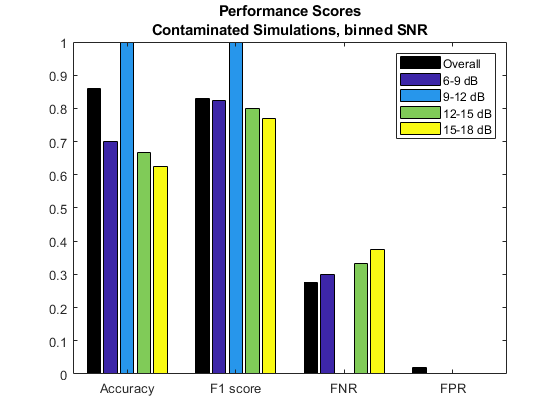

binsSNR = discretize(tcontaminated.SNRdB,edges);

[acc,fpr,fnr,f1] = splitapply(@scoreModel,tcontaminated.ContaminatedTrue,tcontaminated.ContaminatedPred,binsSNR);
% Plot scores for comparison
c = categorical({'Accuracy','F1 score','FNR','FPR'});
b = bar(c,[[scoresOA.acc acc']; [scoresOA.f1 f1']; [scoresOA.fnr fnr']; [scoresOA.fpr fpr']],'FaceColor','flat');
ylim([0 1])
legend({'Overall','6-9 dB','9-12 dB','12-15 dB','15-18 dB'})
title({'Performance Scores';'Contaminated Simulations, binned SNR'})
b(1).CData = [0 0 0];
for k = 1:length(unique(binsSNR))
    b(k+1).CData = k;
end

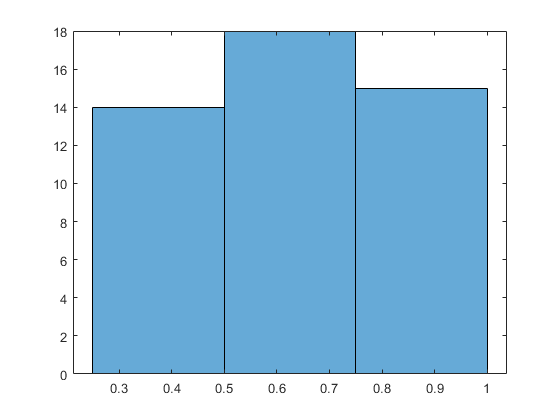

% Fraction of signal block contaminated
edges = 0.25:0.25:1;
histogram(tcontaminated.FracBlockContaminated,edges)